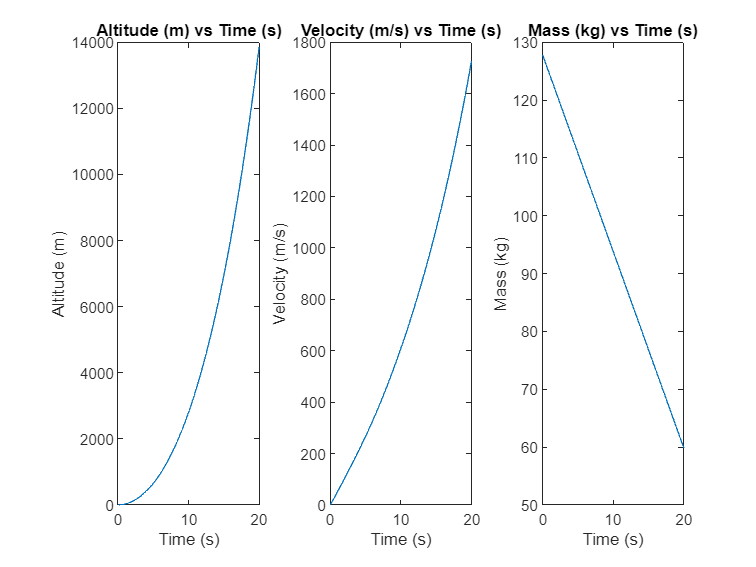

if ~exist('S', 'var')
    denebsim
end

if ~exist('Deneb', 'var')
    ROCKET
end

plotPhase(T_Powered, S_Powered)

EROORR!!!! no solultion for m2, are you doing subsonic?


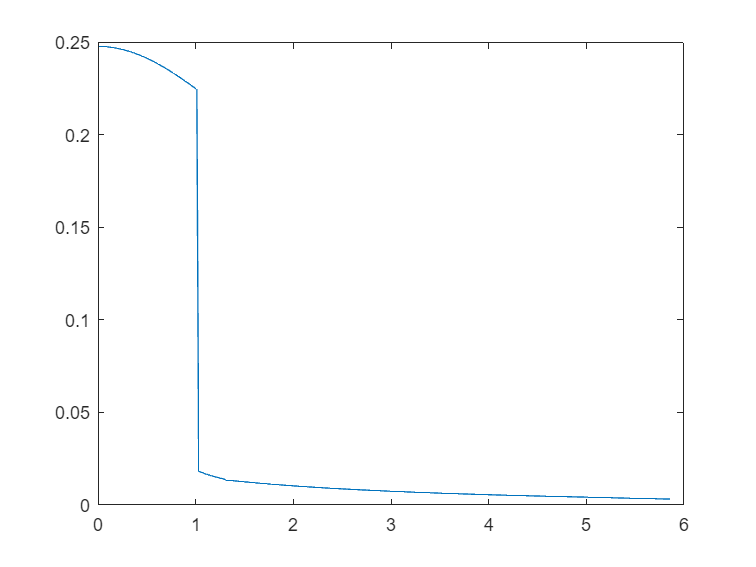

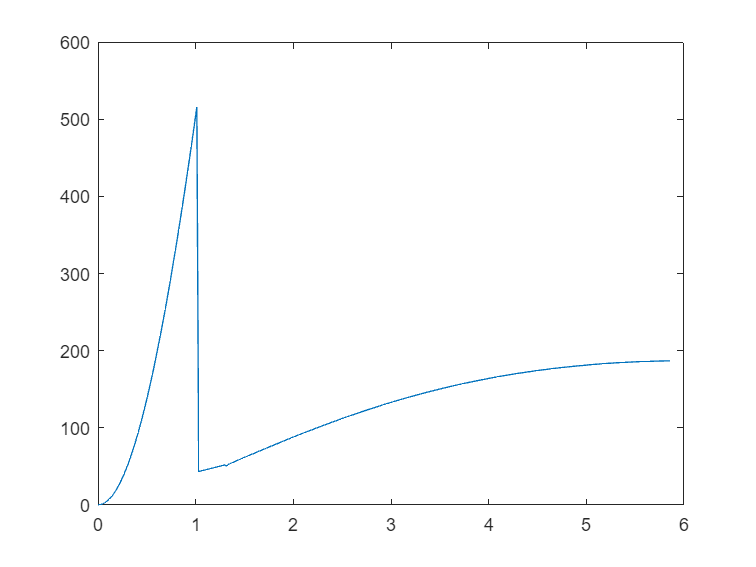

[C_D, maxqstuff] = dragAnalysis(T_Powered, S_Powered, Deneb.DIAMETER^2*pi/4, Deneb);

maxqstuff

maxqstuff = 1.0e+03 *

    0.5159    0.0010    1.0155


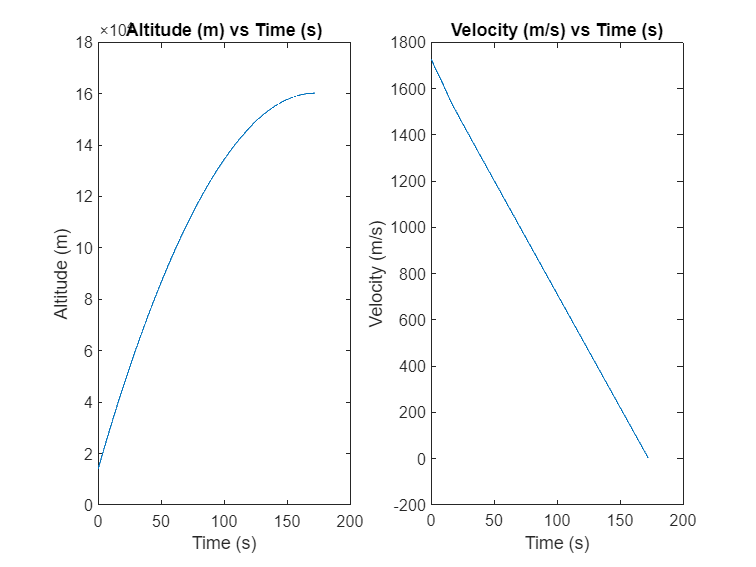

plotPhase(T_Ballistic, S_Ballistic)

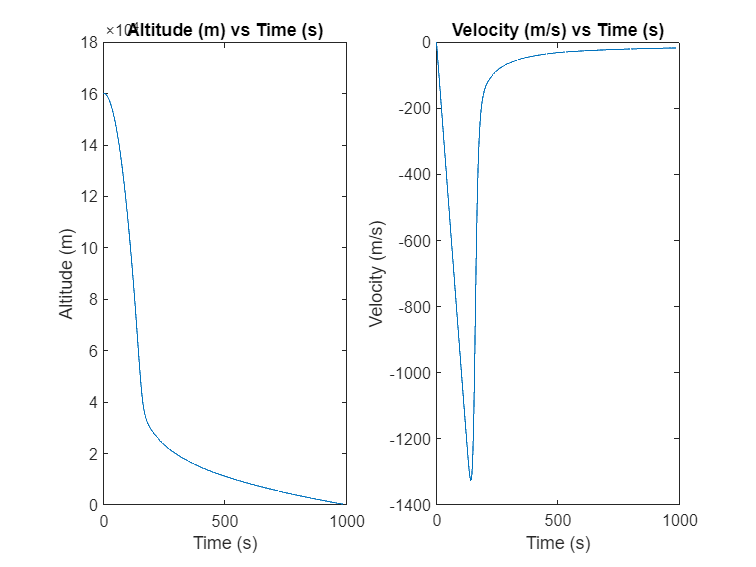

plotPhase(T_Drogue, S_Drogue)

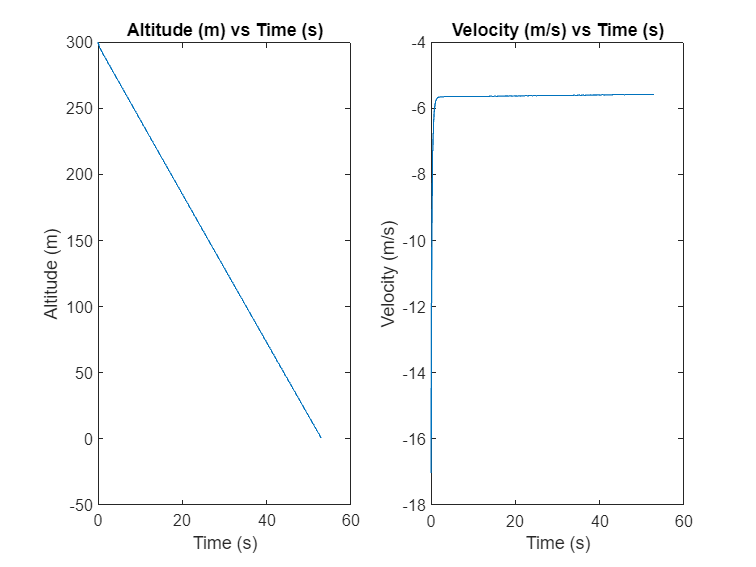

plotPhase(T_Main, S_Main)

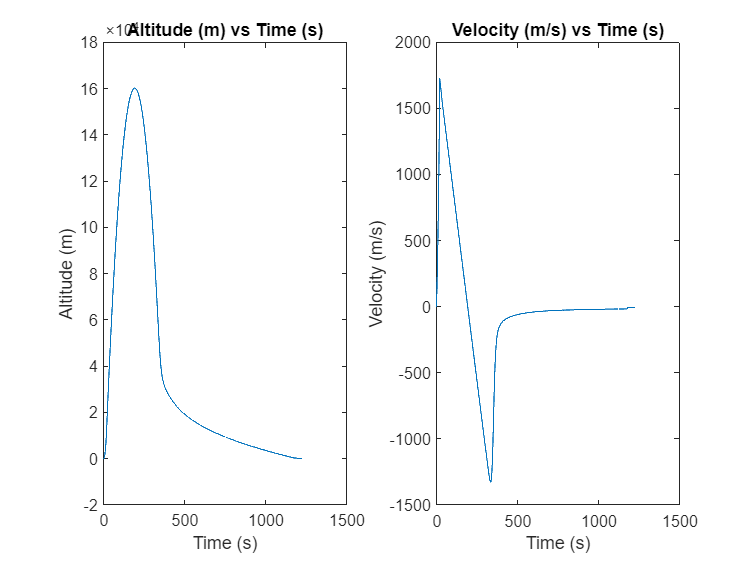

plotPhase(T, S)

sprintf("Max drag force: %d N, mach at point: %.3d, altitude at point: %d m", maxes)

ans = "Max drag force: 3.295457e+03 N, mach at point: 9.858e-01, altitude at point: 1.270816e+03 m"

function plotPhase(T, S)
    Ssize = size(S);
    svarcount = Ssize(2);

    figure

    svars = ["Altitude (m)", "Velocity (m/s)", "Mass (kg)"];
    for i=1:svarcount
        subplot(1,svarcount,i)
        plot(T,S(:,i))
        title(svars(i)+" vs Time (s)")
        xlabel("Time (s)")
        ylabel(svars(i))
    end

end

function [C_D, maxes] = dragAnalysis(T, S, refA, Deneb)
    C_D = [];
    F_D = [];
    maxes = [0, 0, 0];
    for i=S'
        h = i(1);
        v = i(2);
        [T_, a, P, rho] = atmosisa(0, "extended","on", "action","None");
        if i(2)/a > 1
            Fd = SonicSkinDrag(h, v, Deneb);
        else
            Fd = SubSonicSkinDrag(h, v, Deneb);
        end
        Fd = Fd+PressureDrag(h, Deneb);
        F_D(end+1) = Fd;
        C_D(end+1) = 2*Fd/refA/rho/(i(2)^2);
        if Fd > maxes(1)
            maxes(1) = Fd;
            maxes(2) = v / a;
            maxes(3) = h;
        end
    end
    figure
    plot(calcMach(S), C_D)
    figure
    plot(calcMach(S), F_D)
end

function mach = calcMach(S)
    mach = [];
    for i=S'
        [T_, a, P, rho] = atmosisa(i(1), "extended","on", "action","None");
        mach(end+1) = i(2)/a;
    end
end

function Fd=Drag(Cd, refA, rho, v)
    Fd = .5 * Cd * refA * rho * v^2;
end